# Question: 

# What should be the roof overhang's measurement for an average house temperature to be consistently comfortable over 4 seasons?

#### Brooke Moss, Cherry Pham

This is a design question, it contributes to solar houses’ design/construction. Passive solar houses are designed to retain the maximum amount of heat in colder months. However, without controls to keep the heat away or cool the houses down, they will overheat in hotter months. Controls are crucial in increasing solar houses’ usability throughout the year, instead of solely in cold months. By asking this question, we will learn about the most efficient length for a roof overhang to maintain almost constant and comfortable temperature throughout the year.

## Methodology:

We’re going to model the air temperature inside the house at 4 points in 4 seasons: summer solstice, winter solstice, vernal equinox, and autumnal equinox, each over a 24 hour period.

**Assumptions:**

- The radiation gained by the aperture will go straight to the thermal mass, neglecting the conduction between the absorber and the thermal mass. We’re also assuming that the thermal mass is receiving 100% of the heat from solar radiation. This is a bad assumption because it is simplifying the model and making the house gain more heat than it is supposed to. The skewed data caused by this calculation will affect the credibility of our verification and validation.

- The house is only losing heat through the back wall, the other walls and window have extremely high levels of insulation. 

- The temperature at the solstices and the equinoxes can represent the general temperature of that season. This is a good assumption because it makes the model easier to read as we are only modeling the house’s heat in one day, at 4 peaks of different seasons.

- Similarly, a lot of our parameters are taken from “average”, “typical”, or “recommended” values, with the assumption that these values can represent a range of different passive solar houses.

- We’re also neglecting convection that comes from the walls and the window to the room temperature as we assume they are negligible.

- We also made assumptions like the house starts at the same temperature of each simulation, the temperature on the day of the equinoxes and the solstices is also an assumed value that is supposed to represent every other year.

**Stock and flow diagram:**

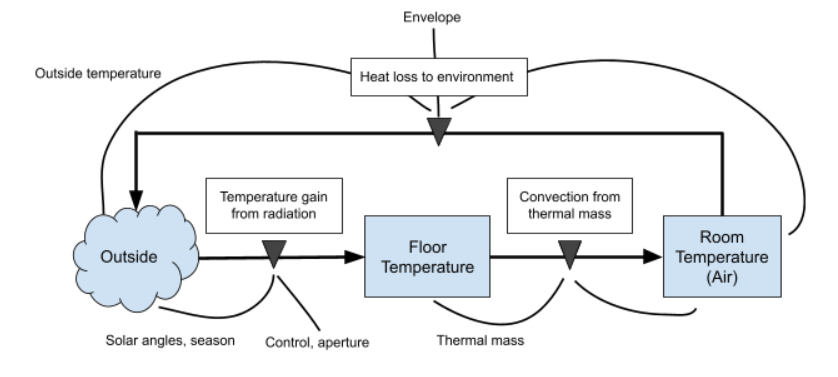

**Parameters:**

The house’s sizing and most measurements are taken from research of measurements for an average, small solar house. Some of the parameters are constants taken from research of the materials we used for the house and research of air and sun properties.

Set Parameters:

- Wall Height 1 (Rear) = 2.5m

- Wall Height 2 (Front) = 3.0m

- Building Depth = 3.0m

- Building Length = 10.0m

- Overhang Angle = 15 degrees below horizontal

- Latitude = 44.422154

- Longitude = -67.906744

% Changing Parameters

% Overhang
o_length = [0.15, 0.5, 0.8, 1.2]; % Overhang length (m); See reference (11)

%Sun angle parameters
s_decang_summer = 23.5; % Solar declination angle for the summer
s_decang_fall = 0; % Solar declination angle for the fall
s_decang_winter = -23.5; % Solar declination angle for the winter
s_decang_spring = 0; % Solar declination angle for the spring

% Temperatures
outTemp = [291, 280, 261]; % Outside temps: Summer, Fall, Winter (K)


Stocks:

- Internal energy (building materials)

- Internal energy (air)

% % Stock Definitions
% T_i = 294; % 294K ~ 70F
% Eair_i = temperatureToEnergy(T_i, a_volume * a_density, a_specific); % Initial Energy of the inside air (J)
% Efloor_i = temperatureToEnergy(T_i, f_volume * f_density, f_specific); % Initial Energy of the floor (J)

Flows:

- Heat absorbed by materials (radiation)

- Heat exchange from materials to indoor air (convection)

- Heat lost through windows from indoor air (conduction)

Controls:

- Control (m) - length of overhang

- Aperture (m) - height of windows

- Season

- Absorber - specific heat capacity of building materials

- Envelope - insulating capacity of building materials

Equations:

- **Radiation: dFdt = e * I * ProjectedArea**

- ProjectedArea = b_length * (cos(s_angle)*w_height - o_length*cos(o_angle)*sin(s_angle))

- Sun angle: alpha = 15 * ((t + (4 * (Longitude - 15 * (GMT)) + EoT/60))-12);

- **Convection: dUdt = hA(Tair - Tmaterial)**

- **Conduction: dUdt = -kA(deltaT)/d**

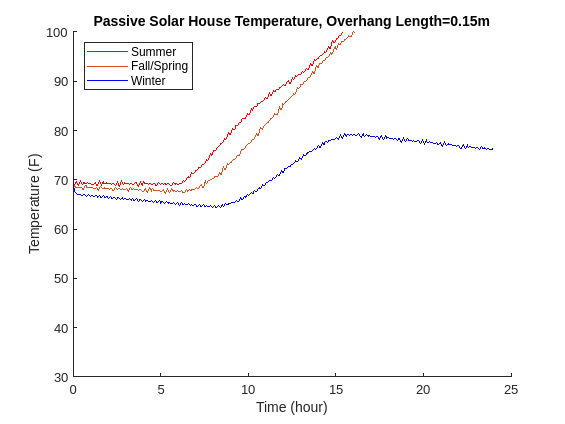

% Test Model
clf;
figure(1)
hold on;
title('Passive Solar House Temperature, Overhang Length=0.15m');
xlabel('Time (hour)');
ylabel('Temperature (F)')
[Time, A_tempS1] = tempSim(s_decang_summer, outTemp(1), o_length(1));
plot(Time/3600, A_tempS1, 'r');
[Time, A_tempF1] = tempSim(s_decang_fall, outTemp(2), o_length(1));
plot(Time/3600, A_tempF1);
[Time, A_tempW1] = tempSim(s_decang_winter, outTemp(3), o_length(1));
plot(Time/3600, A_tempW1,'b');
legend('Summer','Fall/Spring','Winter','Location','northwest')
ylim([30 100])
hold off

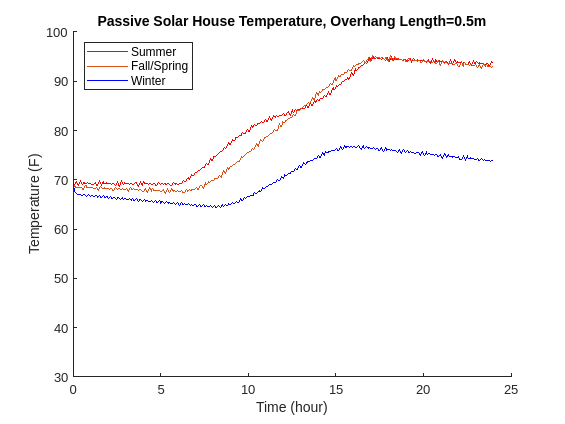

figure(2)
hold on
title('Passive Solar House Temperature, Overhang Length=0.5m');
xlabel('Time (hour)');
ylabel('Temperature (F)')
[Time, A_tempS2] = tempSim(s_decang_summer, outTemp(1), o_length(2));
plot(Time/3600, A_tempS2, 'r');
[Time, A_tempF2] = tempSim(s_decang_fall, outTemp(2), o_length(2));
plot(Time/3600, A_tempF2);
[Time, A_tempW2] = tempSim(s_decang_winter, outTemp(3), o_length(2));
plot(Time/3600, A_tempW2,'b');
legend('Summer','Fall/Spring','Winter','Location','northwest')
ylim([30 100])

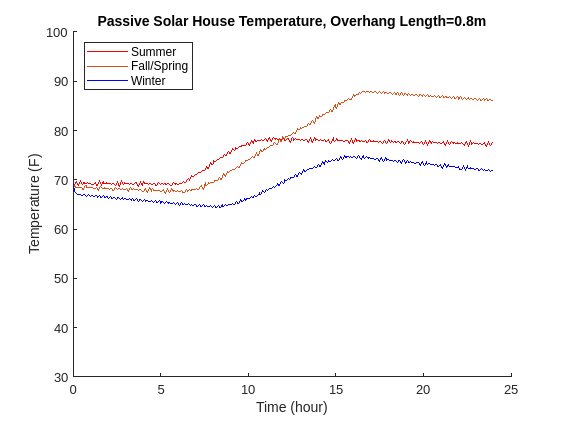

figure(3)
hold on
title('Passive Solar House Temperature, Overhang Length=0.8m');
xlabel('Time (hour)');
ylabel('Temperature (F)')
[Time, A_tempS3] = tempSim(s_decang_summer, outTemp(1), o_length(3));
plot(Time/3600, A_tempS3, 'r');
[Time, A_tempF3] = tempSim(s_decang_fall, outTemp(2), o_length(3));
plot(Time/3600, A_tempF3);
[Time, A_tempW3] = tempSim(s_decang_winter, outTemp(3), o_length(3));
plot(Time/3600, A_tempW3,'b');
legend('Summer','Fall/Spring','Winter','Location','northwest')
ylim([30 100])

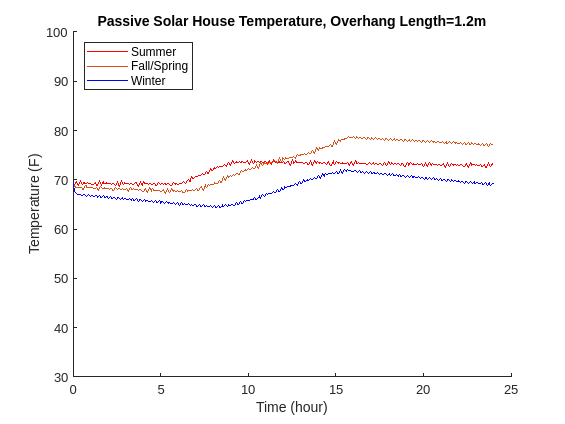

figure(4)
hold on
title('Passive Solar House Temperature, Overhang Length=1.2m');
xlabel('Time (hour)');
ylabel('Temperature (F)')
[Time, A_tempS4] = tempSim(s_decang_summer, outTemp(1), o_length(4));
plot(Time/3600, A_tempS4, 'r');
[Time, A_tempF4] = tempSim(s_decang_fall, outTemp(2), o_length(4));
plot(Time/3600, A_tempF4);
[Time, A_tempW4] = tempSim(s_decang_winter, outTemp(3), o_length(4));
plot(Time/3600, A_tempW4,'b');
legend('Summer','Fall/Spring','Winter','Location','northwest')
ylim([30 100])

**Verification and Validation:**

The temperature should be rising from sunrise (around 6-7 am) and start decreasing once the sun rises above the roofline. Upon looking at the temperature changes in the graph generated to track room temperature, we found that our units were not consistent for time. We also found that the radiation equation was outputting negative values due to the solar angle being negative at points before sunrise and after sunset. Irregular temperature changes are also a good way to tell if there is something wrong with the model. The values produced by this model are based on a fictional house. Although the data were realistic, we can only validate certain elements between calculations: solar angle and radiation, convection from concrete, etc.

## Interpretation:

To answer our modeling question, the most efficient roof overhang is 1.2m. As indicated in the last graph, when the roof overhang is 1.2m, the temperature over the span of 24 hours is consistently within the same range. Since this model has a lot of assumptions, this answer is not very reliable. However, this can act as a good base model that can easily be further developed and applied to the real world. 

**Limitations:**

- The house is set at a certain location in Maine, USA. Therefore, it may have high accuracy if applied to passive solar houses in areas of similar solar angles and climate and low accuracy if applied to houses elsewhere.

- Only account roof overhang length; this model can be further expanded to match the amount of research obtained (e.g: South-facing window is not implemented)

## Citations:

- *Checklist: A Primer for Passive Solar*. Green Built Alliance. (2017, September 11). Retrieved November 3, 2021, from https://www.greenbuilt.org/articles/146-checklist-a-primer-for-passive-solar/.

- *Doe/GO-102001-1105 February 2001 passive solar ... - NREL*. (n.d.). Retrieved November 3, 2021, from https://www.nrel.gov/docs/fy01osti/27954.pdf.

- *How much does The sun heat your house?* Marmott Énergies. (2020, November 21). Retrieved November 3, 2021, from https://marmottenergies.com/much-sun-heat-house/.

- *Insulation materials and their thermal properties*. Greenspec. (n.d.). Retrieved November 3, 2021, from https://www.greenspec.co.uk/building-design/insulation-materials-thermal-properties/.

- *Investigation of Concrete Solar Collector: A Review*. (n.d.). Retrieved November 3, 2021, from https://www.iosrjournals.org/iosr-jmce/papers/RDME-Volume6/RDME-53.pdf.

- Rooij, D. D. (2020, October 28). *Calculation of solar insolation*. Manage risks and maximize ROI for your PV and energy storage projects. Retrieved November 3, 2021, from https://sinovoltaics.com/learning-center/basics/calculation-of-solar-insolation/#:~:text=Solar%20insolation%20(I)%20can%20be,formula%3A%20I%20%3D%20S%20cosZ.

- *The Sun's position*. PVEducation. (n.d.). Retrieved November 3, 2021, from https://www.pveducation.org/pvcdrom/properties-of-sunlight/the-suns-position.

- *Thermal mass*. Greenspec. (n.d.). Retrieved November 3, 2021, from https://www.greenspec.co.uk/building-design/thermal-mass/. *Thermal mass: How to add it to your home*. Rise. (2021, June 15). Retrieved November 3, 2021, from https://www.buildwithrise.com/stories/thermal-mass-in-the-home. 